% SIMULERING AF SYSTEM
% 7 mikrofoner får et input a 1, 3, 10 kHz
% deres input er justeret efter position i array
% 3 ULAer med 3 mikrofoninput i hver 
% DAS på hver ULA - kræver fractional delay
% Frekvensfiltrering før eller efter DAS??
% Sum outputs
% PSD

clc
clear
close all
% Change DAS parameters in DAS.mlx
load('DASParams.mat')

fs = 41.667e3;

%inputAng = 100 
steerAng % Main lobe steering direction from DAS.mlx

steerAng = 35.0100

c = 343;
%c = 1496;
%micTimeOffsets = micArray.*cosd(inputAng)/c
 % inputSig = sin(2*pi*(t+micTimeOffsets')*1000) ...
 %     + sin(2*pi*(t+micTimeOffsets')*3000) ...
 %     + sin(2*pi*(t+micTimeOffsets')*10000);
%inputSig = sin(2*pi*(t+micTimeOffsets').*linspace(1,24e3,length(t)))
%inputSig = sin(2*pi*(t+micTimeOffsets').*randi(24e3,1,length(t)))
zeroPad = 100;
%inputSig = [zeros(7,zeroPad) inputSig zeros(7,zeroPad)];

% tauULA1 = [0,-2.737473007486094e-04,-5.474946014972187e-04];
% tauULA2 = [0,-9.124910024953644e-05,-1.824982004990729e-04];
% tauULA3 = [0,-3.910675724980132e-05,-7.821351449960264e-05];

% Time offset in samples
tauOffset1 = tauULA1*fs; % Mic 1, 4, 7
tauOffset2 = tauULA2*fs; % Mic 2, 4, 6
tauOffset3 = tauULA3*fs; % Mic 3, 4, 5

% Fractional delays TBI

cfULA1 = 1700;
cfULA2 = [cfULA1 4500];
cfULA3 = cfULA2(2);

% -3 dB cut-off
FIRULA1 = makeFIR(cfULA1, 60, fs, 'low');
FIRULA2 = makeFIR(cfULA2, 60, fs, 'bandpass');
FIRULA3 = makeFIR(cfULA3, 60, fs, 'high');

% -6 dB cut-off
% FIRULA1 = fir1(60, 2*cfULA1/fs, 'low');
% FIRULA2 = fir1(60, 2*cfULA2/fs, 'bandpass');
% FIRULA3 = fir1(60, 2*cfULA3/fs, 'high');

% freqz(FIRULA1,1,1024,fs);
% hold on
% freqz(FIRULA2,1,1024,fs);
% freqz(FIRULA3,1,1024,fs);
% hold off

inputAng = linspace(0,360,361)

inputAng =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


%inputAng = linspace(0, 359, 73);
%inputAng = [35];
%inputAng(1) = inputAng(1)+0.5;
%inputAng(end) = inputAng(end)-0.5;
freqs = linspace(0, 24e3, 241);
%freqs = linspace(0, 8e3, 41);
%freqs = [1900]
freqs(1) = freqs(1) + 20;
freqs(end) = freqs(end) - 20;
t = 0:1/fs:0.5;
magRatio = zeros(length(inputAng),length(freqs));

f = waitbar(0,'Starting...','Name','Simulating DAS',...
    'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');

for ang = 1:length(inputAng)
    micTimeOffsets = micArray.*cosd(inputAng(ang))/c;
    for freq = 1:length(freqs)
        inputSig = sin(2*pi*(t+micTimeOffsets')*freqs(freq));

        % Filter inputs 
        inputSigULA1 = filter(FIRULA1,1,inputSig,[],2);
        inputSigULA1 = [zeros(7,zeroPad) inputSigULA1 zeros(7,zeroPad)];
        %inputSigULA1 = [zeros(7,zeroPad) inputSig zeros(7,zeroPad)];
        inputSigULA2 = filter(FIRULA2,1,inputSig,[],2);
        inputSigULA2 = [zeros(7,zeroPad) inputSigULA2 zeros(7,zeroPad)];
        %inputSigULA2 = [zeros(7,zeroPad) inputSig zeros(7,zeroPad)];
        inputSigULA3 = filter(FIRULA3,1,inputSig,[],2);
        inputSigULA3 = [zeros(7,zeroPad) inputSigULA3 zeros(7,zeroPad)];
        %inputSigULA3 = [zeros(7,zeroPad) inputSig zeros(7,zeroPad)];
        
        % Output of each ULA
        ULA1Sum = inputSigULA1(1,zeroPad+round(tauOffset1(1)):end-1-zeroPad+round(tauOffset1(1)))...
            + inputSigULA1(4,zeroPad+round(tauOffset1(2)):end-1-zeroPad+round(tauOffset1(2))) ...
            + inputSigULA1(7,zeroPad+round(tauOffset1(3)):end-1-zeroPad+round(tauOffset1(3)));
        ULA1Sum = ULA1Sum * 1/3;
        
        ULA2Sum = inputSigULA2(2,zeroPad+round(tauOffset2(1)):end-1-zeroPad+round(tauOffset2(1)))...
            + inputSigULA2(4,zeroPad+round(tauOffset2(2)):end-1-zeroPad+round(tauOffset2(2))) ...
            + inputSigULA2(6,zeroPad+round(tauOffset2(3)):end-1-zeroPad+round(tauOffset2(3)));
        ULA2Sum = ULA2Sum * 1/3;
        
        ULA3Sum = inputSigULA3(3,zeroPad+round(tauOffset3(1)):end-1-zeroPad+round(tauOffset3(1)))...
            + inputSigULA3(4,zeroPad+round(tauOffset3(2)):end-1-zeroPad+round(tauOffset3(2))) ...
            + inputSigULA3(5,zeroPad+round(tauOffset3(3)):end-1-zeroPad+round(tauOffset3(3)));
        ULA3Sum = ULA3Sum * 1/3;
        
        arrayOutput = (ULA1Sum.^2 + ULA2Sum.^2 + ULA3Sum.^2);
        %arrayOutput = filter(FIRULA1,1,ULA1Sum).^2 + filter(FIRULA2,1,ULA2Sum).^2 + filter(FIRULA3,1,ULA3Sum).^2;

        %magRatio(ang,freq) = mean(arrayOutput.^2)/mean(sum(inputSig.^2,1))';
        %magRatio(ang,freq) = mean(arrayOutput.^2)/mean(mean(inputSig.^2,2))';
        magRatio(ang,freq) = mean(arrayOutput)/mean(mean(inputSig.^2,2))';
        %magRatio(ang,freq) = mean(arrayOutput.^2)/mean(inputSig(1,:).^2,2)';
        %inputFilteredMag = (inputSigULA1(1,zeroPad:end-zeroPad-1) + inputSigULA1(4,zeroPad:end-zeroPad-1) + inputSigULA1(7,zeroPad:end-zeroPad-1))*1/3 ...
        %    + (inputSigULA2(2,zeroPad:end-zeroPad-1) + inputSigULA2(4,zeroPad:end-zeroPad-1) + inputSigULA2(6,zeroPad:end-zeroPad-1))*1/3 ...
        %    + (inputSigULA3(3,zeroPad:end-zeroPad-1) + inputSigULA3(4,zeroPad:end-zeroPad-1) + inputSigULA3(5,zeroPad:end-zeroPad-1))*1/3;
        %magRatio(ang,freq) = mean(inputFilteredMag.^2)/mean(mean(inputSig.^2,2))';

    end
    setappdata(f,'canceling',0);
    waitbar(ang/length(inputAng),f,sprintf('%d°',inputAng(ang)))
end
delete(f)


## Plot BPs and DF

magRatiodB = 10*log10(magRatio)

magRatiodB =    -0.0045   -0.1007   -0.3569   -0.7930   -1.4125   -2.2471   -3.3191   -4.6758   -6.3560   -8.3717  -10.4851  -11.8004  -11.3081   -9.6970   -8.0532   -6.7640   -5.8631   -5.3050   -5.0321   -4.9845   -5.1124   -5.3689   -5.7218   -6.1579   -6.6718   -7.2719   -7.9708   -8.7764   -9.6954  -10.7324  -11.8939  -13.1907  -14.6248  -16.1717  -17.6883  -18.6912  -18.5176  -17.1510  -15.2574  -13.3725  -11.6872  -10.2426   -9.0366   -8.0498   -7.2639   -6.6604   -6.2194   -5.9252   -5.7609   -5.7072
   -0.0044   -0.1006   -0.3563   -0.7917   -1.4101   -2.2432   -3.3131   -4.6669   -6.3432   -8.3538  -10.4629  -11.7820  -11.3021   -9.6985   -8.0562   -6.7659   -5.8631   -5.3028   -5.0277   -4.9781   -5.1042   -5.3592   -5.7108   -6.1457   -6.6584   -7.2570   -7.9540   -8.7571   -9.6732  -10.7067  -11.8639  -13.1558  -14.5844  -16.1260  -17.6408  -18.6532  -18.5012  -17.1527  -15.2660  -13.3815  -11.6944  -10.2476   -9.0393   -8.0504   -7.2627   -6.6574   -6.2150   -5.9194   -5.

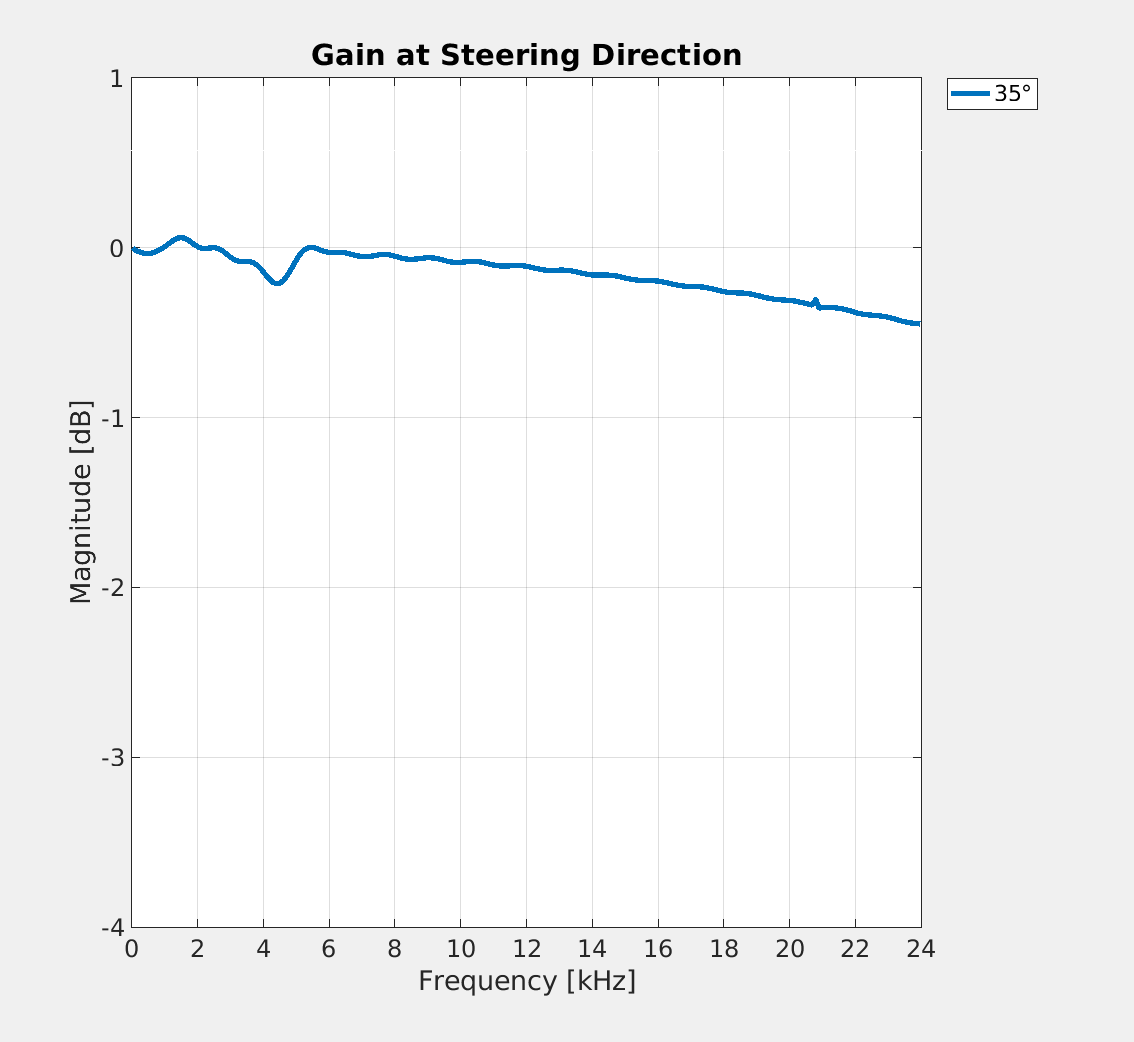

indexHz = find(freqs==1e3); % Find design frequency in sweep list
plotVisibility = 'on';

% figure(1)
% set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
%           'OuterPosition', [0 0 30 20]) %21/2-2*2
% circPlot(freqs(indexHz), inputAng*pi/180, magRatiodB(:,indexHz)', steerAng)

figure(2)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 30])

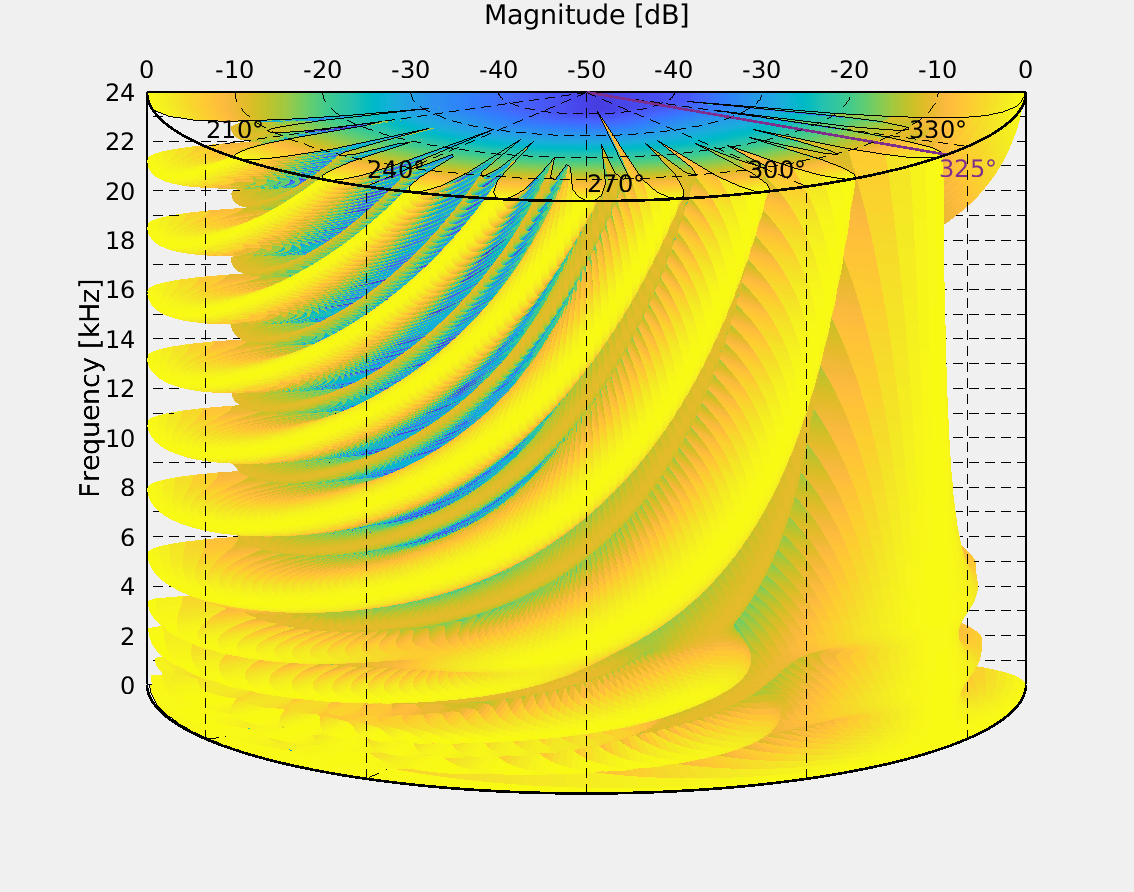

cylindricalPlot(freqs, inputAng*pi/180, magRatiodB', steerAng, [180, 10])

%cylindricalPlot(freqs, linspace(0,2*pi,2*length(inputAng)-1), magRatiodB', steerAng);
%exportgraphics(gcf,'DASSim90.pdf')
% figure(3)
% plot(micArray, zeros(length(micArray),1), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'g')
% hold on
% %text(micArray, zeros(length(micArray),1)+0.5+(-1).^(0:length(micArray)-1)'*0.12, string(round(micArray,3)), 'HorizontalAlignment', 'center', 'FontSize', 12)
% text(micArray, zeros(length(micArray),1)+0.5+[0 0 0.12 -0.12 0.12 0 0]', string(round(micArray,3)), 'HorizontalAlignment', 'center', 'FontSize', 12)
% text(micArray, zeros(length(micArray),1)-0.5, 'Q' + string(0:length(micArray)-1), 'HorizontalAlignment', 'center', 'FontSize', 12)
% pbaspect([8 1 1])
% set(gca,'YTickLabel',{' '})
% xlim([-0.05 1.05])
% grid minor
% hold off
% 
% figure(4)
% set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
%           'OuterPosition', [0 0 18 18])
% mainLobeAng = find(round(inputAng) == round(steerAng))
% plot(freqs,magRatiodB(mainLobeAng,:), 'LineWidth', 4)
% hold on
% ylim([-4 1])
% xlim([0 24e3])
% ytickList = linspace(-4,1,5+1);
% yticks(ytickList(1:1:end))
% yticklabels(string(ytickList(1:1:end)))
% xtickList = linspace(0,24e3,24e3/1000+1);
% xticks(xtickList(1:2:end))
% xticklabels(string(xtickList(1:2:end)/1000))
% ax = gca;
% ax.FontSize = 18;
% xlabel('Frequency [kHz]', 'FontSize', 20)
% ylabel('Magnitude [dB]', 'FontSize', 20)
% title('Gain at Steering Direction', 'FontSize', 22)
% legend(string(round(steerAng))+'°')
% grid
% hold off
%exportgraphics(gcf,'DASMainLobe90.pdf')

## Generate .c and .h files

% Check for "length should be divided by 4 and aligned to 16"
% for f = ["FIRULA1" "FIRULA2" "FIRULA3"]
%     if mod(length(eval('f')),16) ~= 0
%         %padLength = bitand(int(length(FIRULA1) + 3), bitcmp(3))
%         %padLength = 4 * ceil((length(FIRULA1) + 3) / 4);
%         padLength = 16-mod(length(eval('f')),16)
%         eval('f') = zeros(length(eval('f'))+padLength,1)'
%         %mod(length(eval('f'))+padLength,16)
%     end
% end

% if mod(length(FIRULA1),16) ~= 0
%     padLength = 16-mod(length(FIRULA1),16)
%     FIRULA1 = [FIRULA1 zeros(1,padLength)]
% end
% 
% if mod(length(FIRULA2),16) ~= 0
%     padLength = 16-mod(length(FIRULA2),16)
%     FIRULA2 = [FIRULA2 zeros(1,padLength)]
% end
% 
% if mod(length(FIRULA3),16) ~= 0
%     padLength = 16-mod(length(FIRULA3),16)
%     FIRULA3 = [FIRULA3 zeros(1,padLength)]
% end

% % Get the dimensions of the matrix
% FIR1Length = length(FIRULA1);
% FIR2Length = length(FIRULA2);
% FIR3Length = length(FIRULA3);
% 
% % Open the header file for writing
% fid_h = fopen('DAS/main/FIRWeights.h', 'w');
% 
% % Write the header file contents
% %fprintf(fid_h, '#include <complex.h>\n\n');
% fprintf(fid_h, '#ifndef FIRWEIGHTS_H\n');
% fprintf(fid_h, '#define FIRWEIGHTS\n\n');
% 
% fprintf(fid_h, '#define FIR1LENGTH %d\n', FIR1Length);
% fprintf(fid_h, '#define FIR2LENGTH %d\n', FIR2Length);
% fprintf(fid_h, '#define FIR3LENGTH %d\n\n', FIR3Length);
% fprintf(fid_h, 'static __attribute__((aligned(16))) float FIR1WEIGHTS[FIR1LENGTH] = \n\t{');
% for r = 1:FIR1Length
%     fprintf(fid_h, '%f', cast(FIRULA1(r),"single"));
%     if r < FIR1Length
%         fprintf(fid_h, ',');
%     end
% end
% fprintf(fid_h, '};\n\n');
% 
% fprintf(fid_h, 'static __attribute__((aligned(16))) float FIR2WEIGHTS[FIR2LENGTH] = \n\t{');
% for r = 1:FIR2Length
%     fprintf(fid_h, '%f', cast(FIRULA2(r),"single"));
%     if r < FIR2Length
%         fprintf(fid_h, ',');
%     end
% end
% fprintf(fid_h, '};\n\n');
% 
% 
% fprintf(fid_h, 'static __attribute__((aligned(16))) float FIR3WEIGHTS[FIR3LENGTH] = \n\t{');
% for r = 1:FIR3Length
%     fprintf(fid_h, '%f', cast(FIRULA3(r),"single"));
%     if r < FIR3Length
%         fprintf(fid_h, ',');
%     end
% end
% fprintf(fid_h, '};\n\n');
% 
% fprintf(fid_h, '#endif // FIRWEIGHTS_H\n');
% 
% % Close the header file
% fclose(fid_h);
% 
% disp('Header file generated successfully.');


function coeffs_adjusted = makeFIR(Fc, order, fs, type)
if ~exist('type', 'var') 
    coeffs = fir1(order,2*Fc/fs);
else 
    coeffs = fir1(order,2*Fc/fs, type);
end 
[mag, freq] = freqz(coeffs,1,1024,fs);
magdB = 20*log10(abs(mag));
if length(Fc) == 1
    [~, minIndex] = min(abs(magdB + 3));
    Fc_3dB = freq(minIndex);
    Fc_adjusted = Fc * (Fc/Fc_3dB);
    coeffs_adjusted = fir1(order, 2*Fc_adjusted/fs, type);
elseif length(Fc) == 2
    %[~, minIndexLow] = min(abs(magdB + 3));
    minIndexLow = find(abs(magdB)<3,1);
    minIndexHigh = find(abs(magdB(minIndexLow:end))>3,1) + minIndexLow;
    FcLow_3dB = freq(minIndexLow);
    FcHigh_3dB = freq(minIndexHigh);
    FcLow_adjusted = Fc(1) * (Fc(1)/FcLow_3dB);
    FcHigh_adjusted = Fc(2) * (Fc(2)/FcHigh_3dB);
    coeffs_adjusted = fir1(order, 2*[FcLow_adjusted FcHigh_adjusted]/fs, type);
else
    disp("nederen")
end
end